%fname: a string of the filename of the video you want to process
% the the video is not in the same folder, fname should include
% the absolute path to the file
fname = 'C:\Users\kjayaswal\OneDrive - Olin College of Engineering\SOPHOMORE YEAR (25-26)\QEA 3\Project 1- Fidget Spinner\fidget_spinner.mp4'

fname = 'C:\Users\kjayaswal\OneDrive - Olin College of Engineering\SOPHOMORE YEAR (25-26)\QEA 3\Project 1- Fidget Spinner\fidget_spinner.mp4'

Video width (pixels): 720
Video height (pixels): 864
Video processing complete: 0%


Video processing complete: 1%
Video processing complete: 2%
Video processing complete: 3%
Video processing complete: 4%
Video processing complete: 5%
Video processing complete: 6%


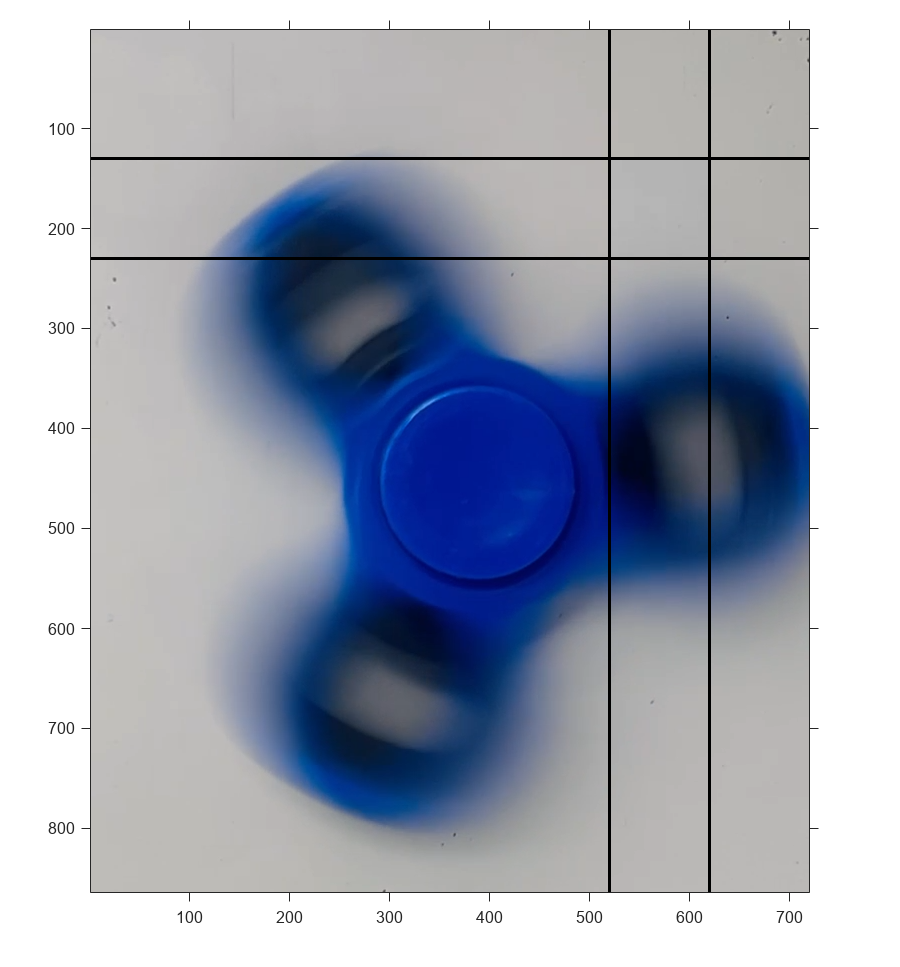

%window_bounds: a MATLAB struct that indicates the boundaries of the
% window to use for averaging the pixel value.
window_bounds = struct();
window_bounds.top = 130;
window_bounds.bottom = 230;
window_bounds.left = 520;
window_bounds.right = 620;
%show_image: a boolean (0 or 1) that determines whether or not the video
% of the fidget spinner is displayed during processing
% set show_image to 1 if you are still trying to figure out
% the boundaries of the window to use
% set show_image to 0 to process the video faster
show_image = 1;
%Converts the video file of a fidget spinner to a time signal
%by computing the average pixel value in a window for each frame
%OUTPUTS:
%y: a list of the averaged pixel value in the window
%Fs: framerate of the video
[y,Fs] = video_to_signal(fname,window_bounds,show_image);

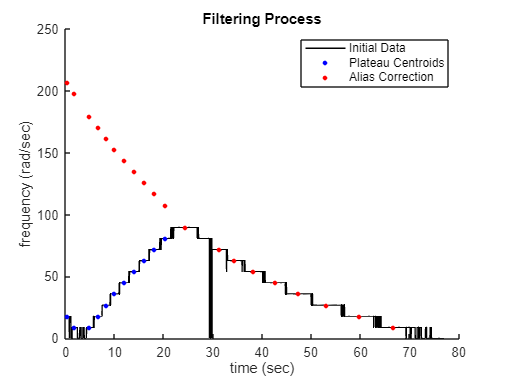

%T_window: width of FFT window (in seconds) .7 is usually good
T_window = .7;
%q: a parameter used to filter which portions of frequency curve to use
% (filter is by width of flat portions of curve)
% value should be in interval [0,1]
% values closer to 1 are most "exclusive".
% .6 is a pretty good value to choose
q = .6;
%showAnalysis: boolean that turns visualization on/off
showAnalysis = 1;
%uses FFT and some filtering tricks to extract angular velocity of fidget
%spinner as a function of time
%OUTPUTS:
%tlist: list of times for measured values of angular frequency
%omega_list: measured value of angular frequency
[tlist,freq_list] = fidget_spinner_FFT(y,Fs,T_window,q,showAnalysis);

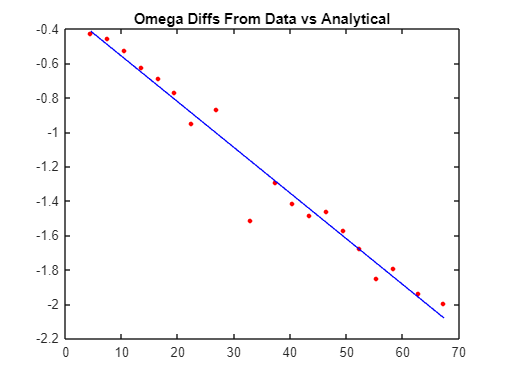

% period_list = (2*pi)./freq_list;
% omega_list = 1./period_list;
% tlist
omega_list = freq_list/3;

alpha_list = diff(omega_list)./diff(tlist);
omega_mid_list = (omega_list(1:end-1)+omega_list(2:end))/2;

figure()
plot(omega_mid_list,alpha_list,'ro','MarkerFaceColor','r','markersize',3)

coeff_vec = polyfit(omega_mid_list, alpha_list, 1);
omega_range = linspace(min(omega_mid_list),max(omega_mid_list),100);
hold on
plot(omega_range,omega_range*coeff_vec(1)+coeff_vec(2), 'b')
title('Omega Diffs From Data vs Analytical')

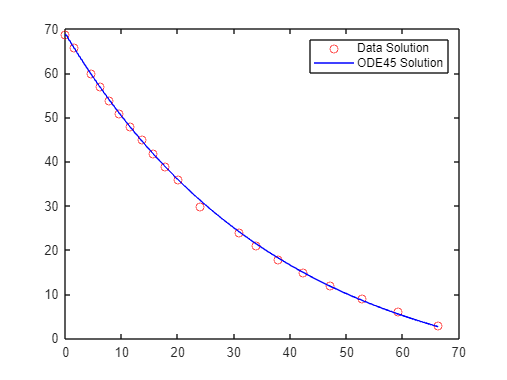

omega_0 = omega_list(1);
tf = tlist(end);
t0 = 0;
f_anonymous = @(t_in,omega_in) coeff_vec(1)*omega_in + coeff_vec(2);
[t_list, x_list] = ode45(f_anonymous,[t0,tf],omega_0);

figure;
plot(tlist, omega_list, 'o', 'DisplayName','Data Solution', 'Color','r'); hold on;
plot(t_list, x_list, 'DisplayName','ODE45 Solution','Color', 'b');
legend;
hold off;

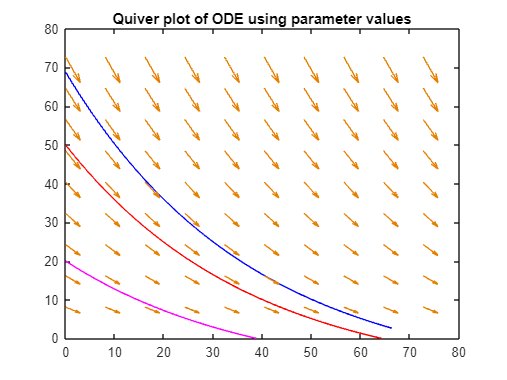

[t,x] = meshgrid(linspace(0, 80, 100), linspace(0, 80, 100));
dt = ones(size(t));
dx = coeff_vec(1).*x + coeff_vec(2);

figure;

plot(t_list, x_list, 'DisplayName','Solution 1','Color', 'b'); hold on;

[t_list_2, x_list_2] = ode45(f_anonymous,[t0,tf],50);

[t_list_3, x_list_3] = ode45(f_anonymous,[t0,tf],20);

plot(t_list_2, x_list_2, 'DisplayName','Solution 2','Color', 'r'); hold on;

plot(t_list_3, x_list_3, 'DisplayName','Solution 3','Color', 'm'); hold on;

sc = 10; 
scale_factor = 3;
t_quiver = t(1:sc:end, 1:sc:end);
x_quiver = x(1:sc:end, 1:sc:end);
dt_quiver = dt(1:sc:end, 1:sc:end);
dx_quiver = dx(1:sc:end, 1:sc:end);

quiver(t_quiver, x_quiver, scale_factor*dt_quiver, scale_factor*dx_quiver, 'AutoScale','off', 'Color', [0.9 0.5 0])
axis ([0 80 0 80]);
title("Quiver plot of ODE using parameter values")
hold off;

omega_0 = omega_list(1);

Unrecognized function or variable 'omega_list'.

tf = tlist(end);
t0 = 0;
f_less_dense = @(t_in,omega_in) 0.5*coeff_vec(1)*omega_in + 0.5*coeff_vec(2);
[t_list_less_dense, x_list_less_dense] = ode45(f_less_dense,[t0,tf],omega_0);
plot(t_list_less_dense, x_list_less_dense); hold on;

plot(t_list, x_list, 'DisplayName','Solution 1','Color', 'b'); hold on;

f_denser = @(t_in,omega_in) 2*coeff_vec(1)*omega_in + 2*coeff_vec(2);
[t_list_denser, x_list_denser] = ode45(f_denser,[t0,tf],omega_0);
plot(t_list_denser, x_list_denser)

f_densest = @(t_in,omega_in) 4*coeff_vec(1)*omega_in + 4*coeff_vec(2);
[t_list_densest, x_list_densest] = ode45(f_densest,[t0,tf],omega_0);
plot(t_list_densest, x_list_densest)

% Define density ratios
density_ratios = [0.5, 1, 2, 4];
t0=0;

% Define corresponding ODE functions
f_list = {
    @(t, omega) 0.5*coeff_vec(1)*omega + 0.5*coeff_vec(2), ...
    @(t, omega) coeff_vec(1)*omega + coeff_vec(2), ...
    @(t, omega) 2*coeff_vec(1)*omega + 2*coeff_vec(2), ...
    @(t, omega) 4*coeff_vec(1)*omega + 4*coeff_vec(2)
};

% Compute stop times
stop_times = zeros(size(density_ratios));
for i = 1:length(f_list)
    [t_sim, omega_sim] = ode45(f_list{i}, [t0, tf], omega_0);
    idx = find(omega_sim <= 0.01, 1); % threshold for "stopped"
    if ~isempty(idx)
        stop_times(i) = t_sim(idx);
    else
        stop_times(i) = tf; % fallback if never reaches zero
    end
end

Unrecognized function or variable 'tf'.


% Normalize by stop time at density ratio = 1
t_star = stop_times(2); % index 2 corresponds to ratio = 1
normalized_stop_times = stop_times / t_star;

% Plot
figure;
plot(density_ratios, normalized_stop_times, 'o-', 'LineWidth', 2);
xlabel('\rho_{fem} / \rho_{fid}');
ylabel('t_{stop} / t^*_{stop}');
title('Normalized Stop Time vs. Density Ratio');
grid on;
